TFbinding_sites_file = fopen('factor_pos_separated/factorbookMotifPos.txt','rt');
thisline_TF = fgetl(TFbinding_sites_file);

current_chr = '';
x = 0; % number of regulatory regions covered
loading = waitbar(0,'Please wait...');
loading2 = waitbar(0,'Please wait...');
i = 0

i = 0

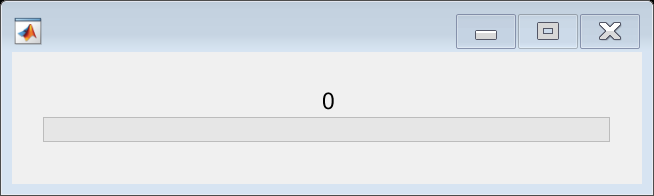

Error using waitbar (line 103)
The second argument must be a message character vector or a handle to an existing waitbar.

while true
    r = x/24;
    waitbar(r,loading,string(r));
    
    if ~ischar(thisline_TF); break; end  %end of file
    
    x = x+1;
    C = strsplit(thisline_TF,"\t");
    chromosome = C(1,2);
    current_chr = string(chromosome{1});

    output_filename = strcat('factor_pos_separated/', string(chromosome{1}), '_TF_pos.txt');
    output_file = fopen(output_filename, 'wt');
%     fprintf(output_file,'%12s\t %12s\t %12s\n','start', 'stop', 'TF_id');
    
    while true
        r = i/1000000;
        waitbar(r,loading2,string(r));
    
        i = i+1;
        start = C(1,3);
        stop = C(1,4);
        start = str2double(start{1});
        stop = str2double(stop{1});
        TF_id = C(1,5);
        TF_id = TF_id{1};
        
        strand = C(1,7);
        strand = strand{1};
        strand = string(strand);
%         fprintf(output_file,'%12d\t %12d\t %12s\t %12s\n',start, stop, TF_id, strand);
        
        thisline_TF = fgetl(TFbinding_sites_file);
        if ~ischar(thisline_TF); break; end  %end of file
        C = strsplit(thisline_TF,"\t");
        chromosome = C(1,2);
        if current_chr ~= chromosome{1}
            break;
        end
    end
    
    fclose(output_file);
    
end

fclose(TFbinding_sites_file);
close(loading);
close(loading2);
x
